# Analyze heat capacity from DR

This routine is intended at fitting Cp data on Y-substituted TmVO4 acquired with our DR used in the Dynacool PPMS of the Lee lab

## Average data

Import data and compute average of data points taken at same setpoint temperature

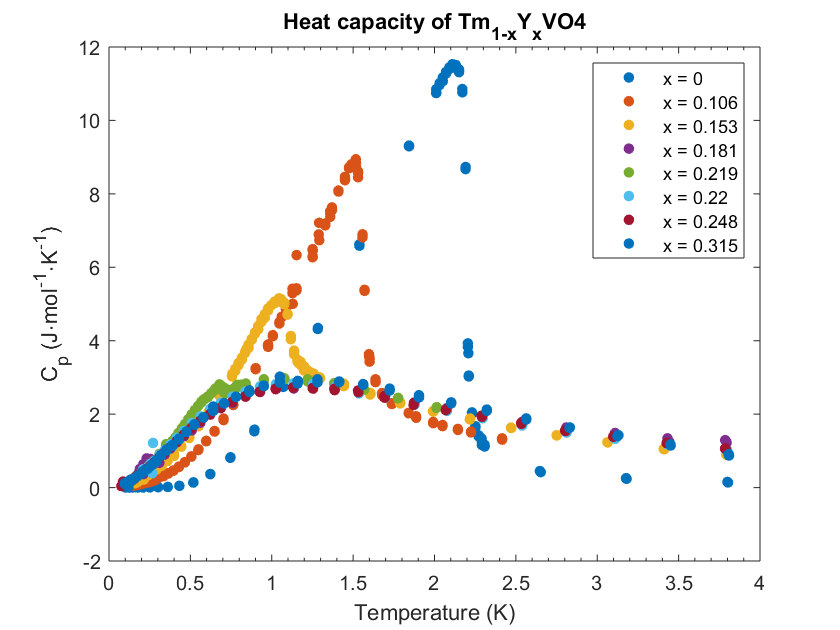

Structure containing averaged data is called avgData


YTmVO4_primary_analysis;

% run script that imports and computes the average of Cp data of all
% desired compositions

### Plot averaged data

#### Plot averaged Cp data for YTmVO4 x<xc

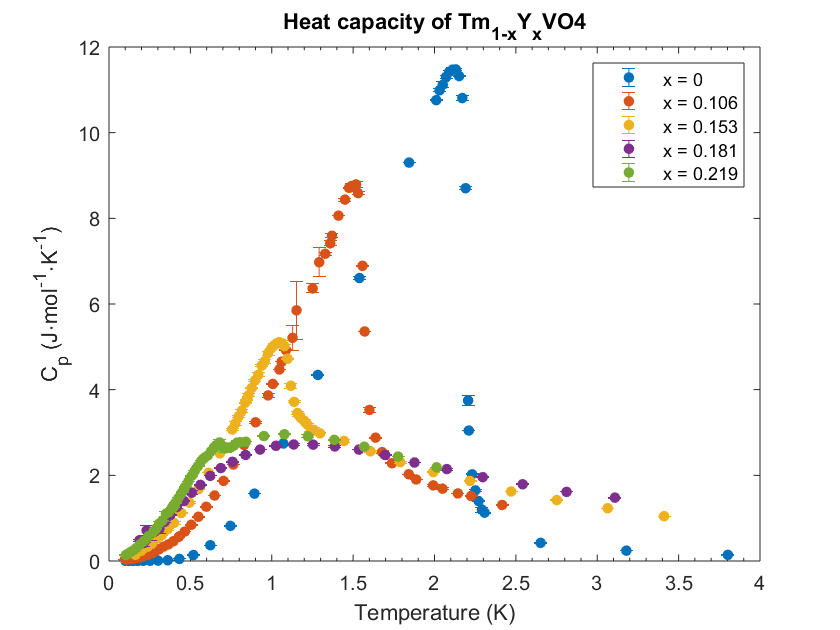

Lord = L-3;% index of the last dataset with Cp jump
plotAvgCp(avgData,dpg,1,Lord)
title(ttlCpY)

#### Plot averaged data for x>xc

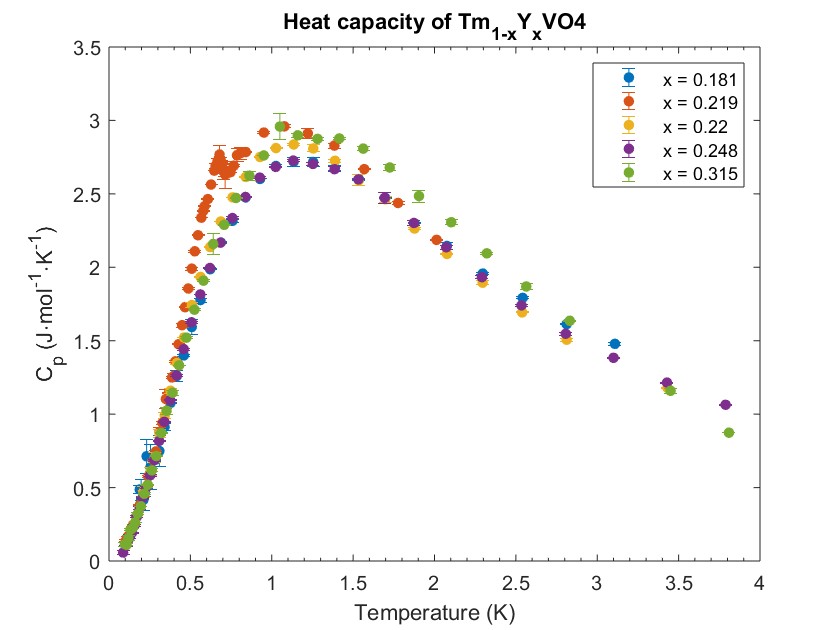

plotAvgCp(avgData,dpg,Lord-1,L)
title(ttlCpY)

## Fit data

### Fit parameters

Tmfmax = [2.1,1.4,0.9,0.2,0.68];% Maximum temperature of mean-field jump for x=0 to x=0.219
% This is a visual estimate of the temperature below which Cp shows a mean-field jump. It only applies for x<xc.
Tc = [2.2,1.57,1.11,0.24,0.69];% Transition temperature
Tschmin = [2.3,1.7,1.2,0.25,0.7];% temperature above which the data are essentially Schottky-like
x0 = [1e-7 0.5];% range of the pseudospin

### Fit mean-field jump for pure TmVO4

    'Coeffsnorm names'    'Amf'



    8.3047



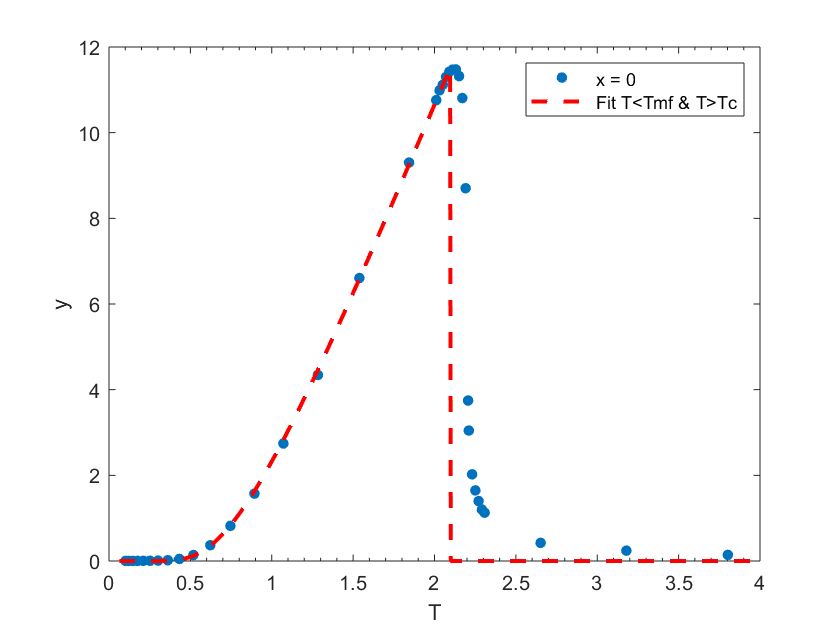

for i=1
    ftmf = fittype(@(Amf,T) fitCpmf(T,Tc(i),Tmfmax(i),Amf),'independent', 'T', 'dependent', 'y' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    opts.StartPoint = [1];% Amf,An,mu,sgm in this order
    opts.Lower = [0];
%     opts.Upper = [Inf Inf 5 5 ];

% Fit mean-field heat capacity jump to data below Tmfmin
    disp(['Coeffsnorm names',coeffnames(ftmf)'])
    [avgData(i).fitmf, avgData(i).ffgof] = fit(avgData(i).T',avgData(i).Cp',ftmf,opts);
    disp(coeffvalues(avgData(i).fitmf))
    figure( 'Name', 'Schottky anomaly' );
    p0 = plot(avgData(i).T', avgData(i).Cp','.' , 'markers',18);%,'DisplayName','x = 0.32');
    hold on
    p2 = plot(avgData(i).fitmf,'--r');%,'DisplayName','Normal');
    legend({['x = ',num2str(dpg(i))],'Fit T<Tmf & T>Tc'})
end

### Extrapolate fit below Tmfmax up to Tc

G = [0.01:0.01:0.48,0.5-logspace(-2,-15,50)];% range of pseudospin
Tfit = ones(length(Tc),length(G));
for ii=1:2
    avgData(i).fp = @(x) (fmf(x,avgData(i).fitmf.Amf));% Mean-field fitting function below Tmfmin
    Tfit(ii,:) = Tc(ii)*2*G./atanh(2*G);% temperature interval corresponding to the full pseudospin interval
%     fplot(avgData(i).fp,x0);% plot the function on its full interval for each doping level
%     plot(Tfit(ii,:),f(G))% plot Cp fit function on the temperature interval for each doping
end

#### Plot data and extrapolated fit as a function of temperature

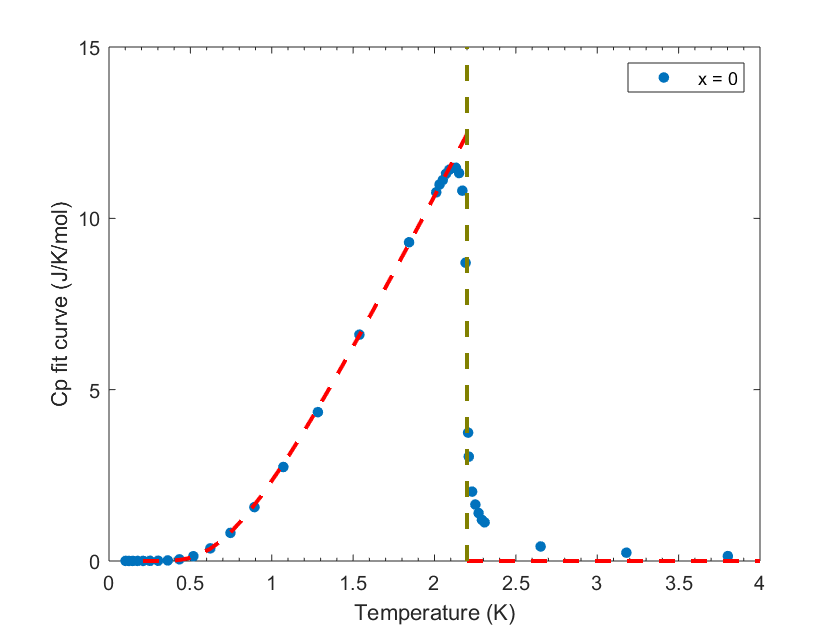

for ii=1
    figure 
    plot(avgData(ii).T,avgData(ii).Cp,'.')
    hold on
    plot(Tfit(ii,:),avgData(ii).fp(G),'--r');%,'DisplayName',['x = ',num2str(dpg(ii))])
    line([Tc(ii),max(xlim)],[0,0],'Color','red','LineStyle','--')
    line([Tc(ii),Tc(ii)],ylim,'Color',[0.5 0.5 0],'LineStyle','--')
    xlabel('Temperature (K)')
    ylabel('Cp fit curve (J/K/mol)')
    legend(['x = ',num2str(dpg(ii))])
hold off
end

## Fit data for x>0

### Compute average gap delta0 from transition temperature

See Gehring1976a equation 5.

pb = @(t,d) 1/sqrt(pi)*integral(@(u)exp(-u^2)/(cosh(d*u/t)^2),-inf,inf,'ArrayValued',true)-t

pb = function_handle with value:
    @(t,d)1/sqrt(pi)*integral(@(u)exp(-u^2)/(cosh(d*u/t)^2),-inf,inf,'ArrayValued',true)-t


% pb stands for phase boundary; 
% here t is a reduced temperature t = T/(dpg(i).lambda), where lambda is defined in the paper
% and d is a reduced spread in the strain distribution:d = Delta_0/(k_B.dpg(i).lambda)

dpg(i)*lambda = T_D(Delta_0=0) = T_D(x=0) T_D(pureTmVO4) = Tc(1) with the notations of this code

fplot(@(t)pb(t,0.1) ,[1e-3 5])

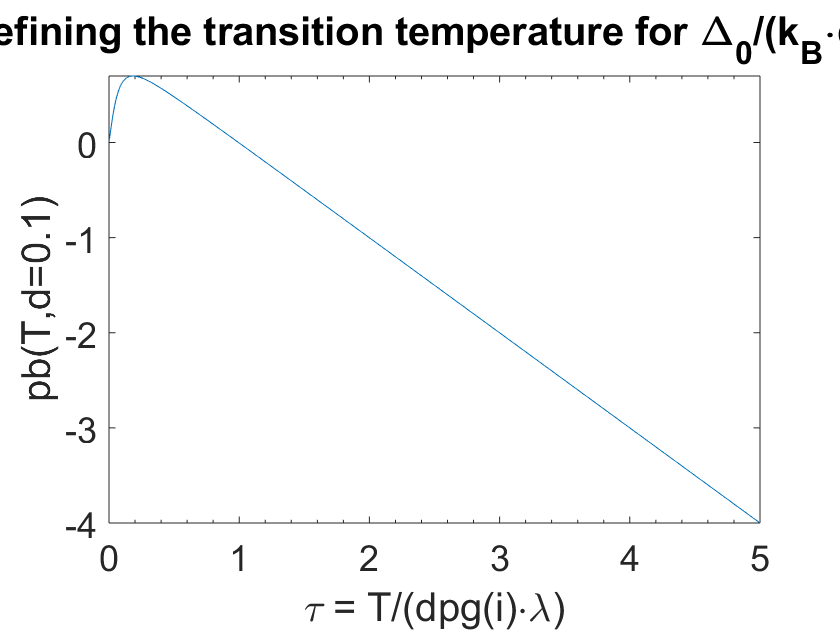

title("Function defining the transition temperature for \Delta_0/(k_B\cdotdpg(i)\cdot\lambda)=0.1")
xlabel("\tau = T/(dpg(i)\cdot\lambda)");ylabel("pb(T,d=0.1)");

#### Reproduce figure 3a of Gehring1976a

td = @(d) fzero(@(t)pb(t,d),[1e-3 5])

td = function_handle with value:
    @(d)fzero(@(t)pb(t,d),[1e-3,5])


fplot(@(d)td(d),[1e-3 1.125])

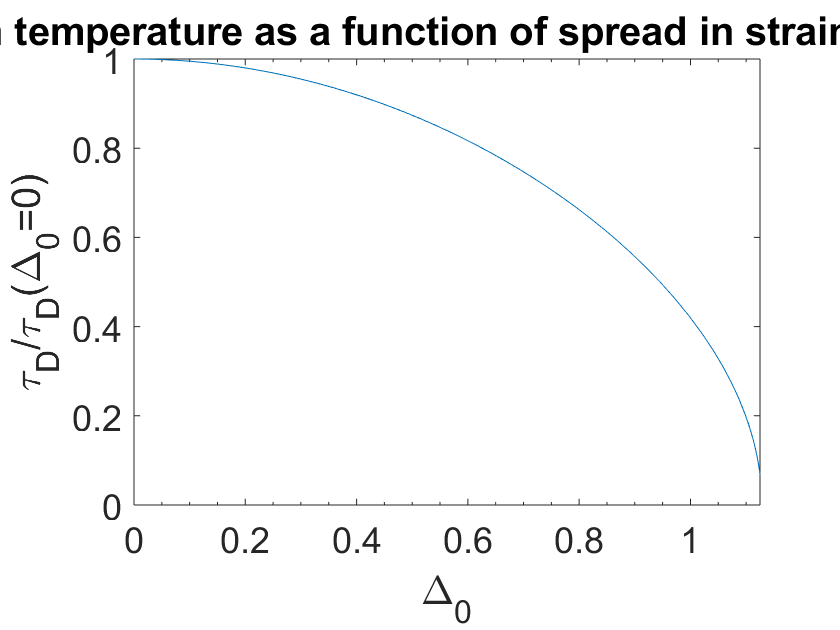

title("Transition temperature as a function of spread in strain distribution");
xlabel("\Delta_0");ylabel("\tau_D/\tau_D(\Delta_0=0)")
ylim([0 1])

delta = function_handle with value:
    @(d)pb(Tc(i)/Tc(1),d)


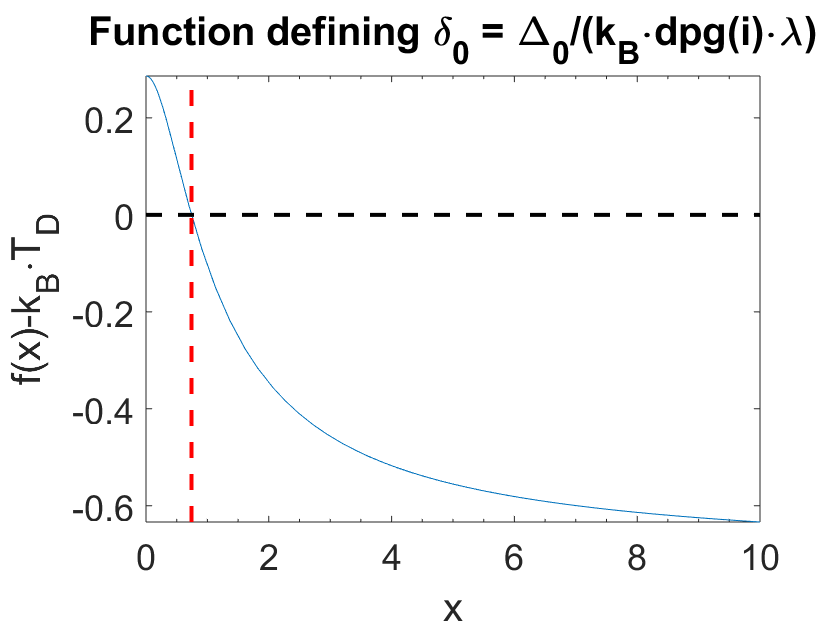

delta0 =     1.0000    1.1646    1.0000    1.0000    1.0000


delta0 = ones(size(Tc));
for i=2
%     delta = @(x) (1-dpg(i))*lambda/sqrt(pi)*integral(@(u)exp(-u^2)/(cosh(x*u/Tc(i))^2),-inf,inf,'ArrayValued',true)-Tc(i)
    delta = @(d)pb(Tc(i)/Tc(1),d)
% The width \Delta_0 of the gaussian strain distribution is the zero of this function
%     delta0(i) = fzero(@(x)delta(x),[0 20])
    d0 = fzero(delta,[0 20]);% note: only works for i>1 (not for i=1)
    fplot(delta,[0 10])
    line(xlim,[0 0],'color','black','linestyle','--')
    line([d0 d0],ylim,'color','red','linestyle','--')
    title("Function defining \delta_0 = \Delta_0/(k_B\cdotdpg(i)\cdot\lambda)");
    xlabel("x");ylabel("f(x)-k_B\cdotT_D")
    delta0(i) = d0*Tc(i)
end

### Compute the pseudospin as a function of temperature

See Gehring1976a equation 4

syms x T u% symbolic math used to derive the expression of pseudospin sigma 
for i=2
%     sigma = @(x,T) 1/sqrt(pi)*integral(@(u)exp(-u^2)*tanh((delta0(i)*u+lambda*x)./T),-inf,inf,'ArrayValued',true)-x
%     sigma = @(x,T) 1/sqrt(pi)*vpaintegral(exp(-u^2)*tanh((delta0(i)*u+lambda*x)./T),u,[-inf,inf])-x
    sigma = @(T,x) 1/sqrt(pi)*int(exp(-u^2)*tanh((delta0(i)*u+x*Tc(1)/(1-dpg(i)))./T),u,[-inf,inf])-x

Sigma is the self-consistent equation defining pseudospin x as a function of temperature T. The value of the pseudospin Sz is simply the solution of sigma=0, hence the use of fzero below.

sigma = function_handle with value:
    @(T,x)1/sqrt(pi)*int(exp(-u^2)*tanh((delta0(i)*u+x*Tc(1)/(1-dpg(i)))./T),u,[-inf,inf])-x


sgm = function_handle with value:
    @(T,x)-x+integral(@(u)tanh((u.*1.16460188521784+x.*2.460850111856823)./T).*exp(-u.^2),-Inf,Inf).*5.641895835477563e-1


sz = function_handle with value:
    @(T)fzero(@(x)sgm(T,x),[1e-3,1])


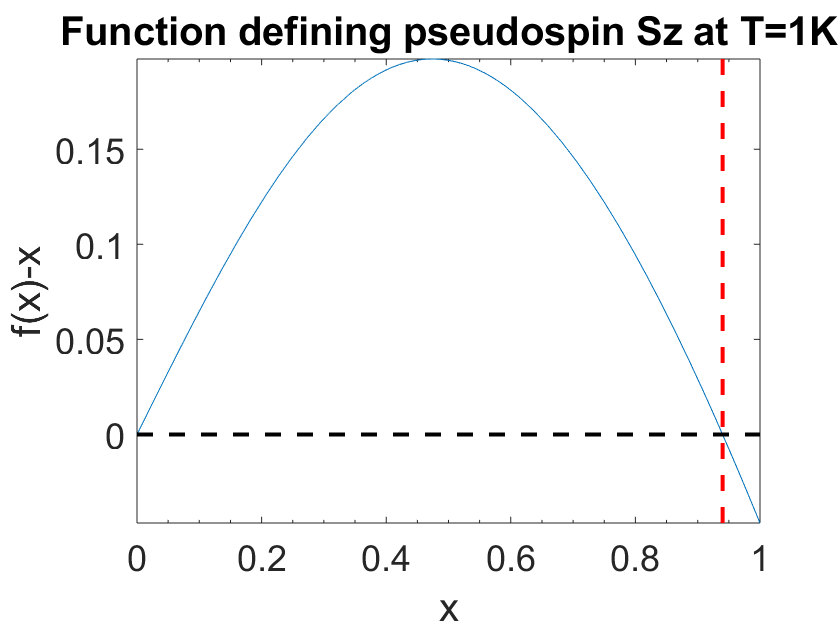

    sgm = matlabFunction(sigma(T,x))% converting into non-symbolic function for computation of values
    sz = @(T) fzero(@(x)sgm(T,x),[1e-3 1])
    Tplot = 1;
    fplot(@(x)sgm(Tplot,x),[0 1])
    line(xlim,[0 0],'color','black','linestyle','--')
    line([sz(Tplot) sz(Tplot)],ylim,'color','red','linestyle','--')
    title("Function defining pseudospin Sz at T=1K");
    xlabel("x");ylabel("f(x)-x");
end

Test function sz

sz(1e-2)

ans = 0.9971

sz(1.6)

ans = 0.7516

sz(2.1)

ans = 0.3110

#### Compute the derivative of sigma, to determine the max temperature of the ordering

sigma goes to zero when increasing T from 0, until dsigma/dx(T,x=0) becomes negative, then the equation sigma(T,x>0)=0 does not have any solution anymore. Therefore, the max temperature of the ordering is reached when dsigma/dx(T,x=0)=0.

dsigma = diff(sigma(T,x),x)

$$dsigma = \frac{5081767996463981\,\int_{-\infty }^{\infty }\left(-\frac{1100\,{\mathrm{e}}^{-u^{2}}\,\left({\tanh\left(\frac{\frac{5244900616302041\,u}{4503599627370496}+\frac{1100\,x}{447}}{T}\right)}^{2}-1\right)}{447\,T}\right)\mathrm{d}u}{9007199254740992}-1$$

g = matlabFunction(dsigma)

g = function_handle with value:
    @(T,x)integral(@(u)(exp(-u.^2).*(tanh((u.*1.16460188521784+x.*2.460850111856823)./T).^2-1.0).*(-2.460850111856823))./T,-Inf,Inf).*5.641895835477563e-1-1.0


fplot(@(x)g(1,x),[0 1])

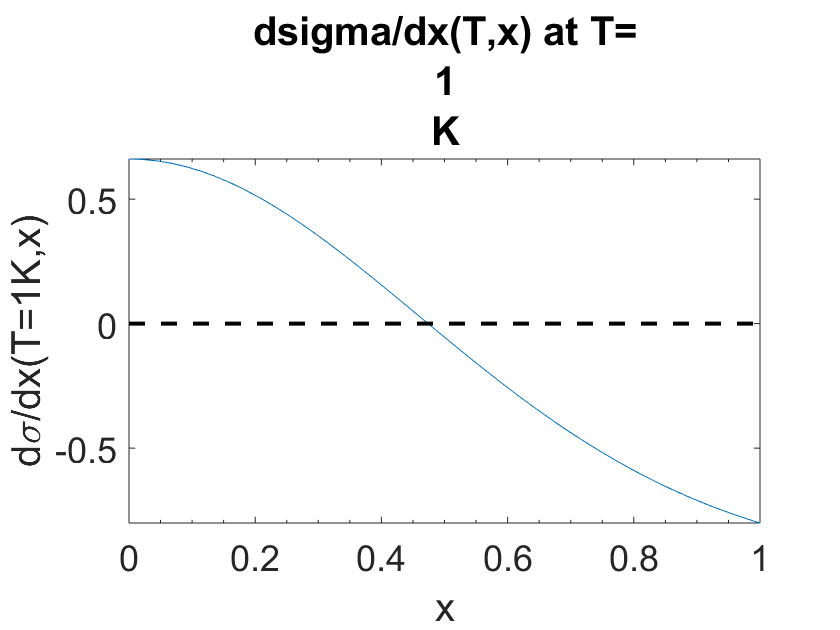

line(xlim,[0 0],'color','black','linestyle','--')
% line([sz(Tplot) sz(Tplot)],ylim,'color','red','linestyle','--')
title(["dsigma/dx(T,x) at T=",num2str(Tplot),"K"]);
xlabel("x");ylabel("d\sigma/dx(T=1K,x)");

g(1,0.39)

ans = 0.1758

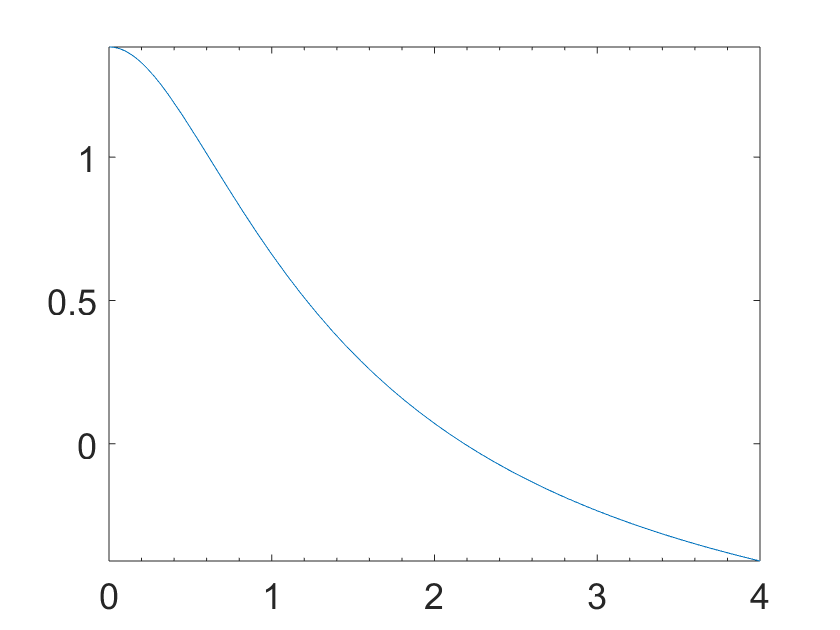

fplot(@(T)g(T,0),[0 4])

g(1e-3,0)

ans = 1.3843

maxT = fzero(@(T)g(T,0),[1e-3 4])

maxT = 2.1833

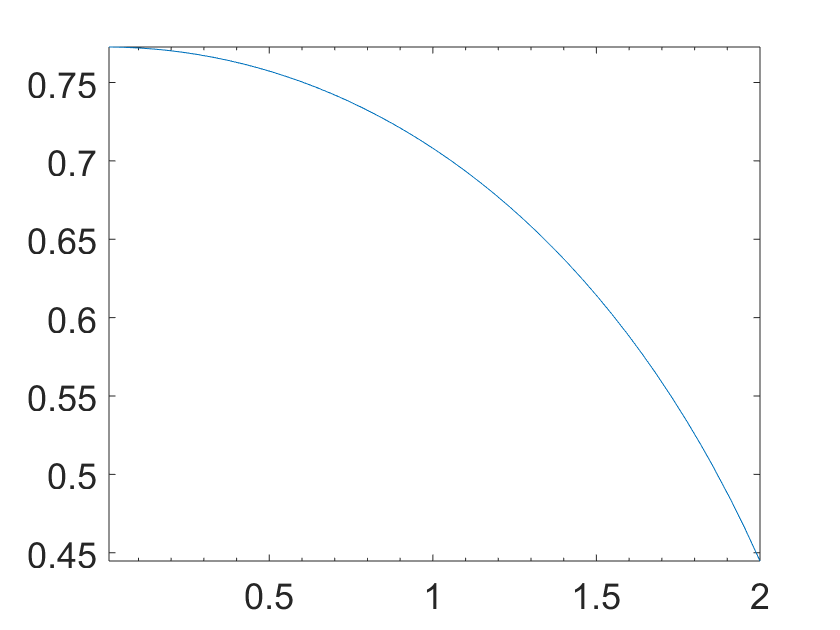

figure
fplot(sz,[1e-2 2])

Need to check: delta0(i) should be of the same OM as Tc(i)